## **Creating the Learning Factory Environment**

## **Creating the Learning Factory Environment**

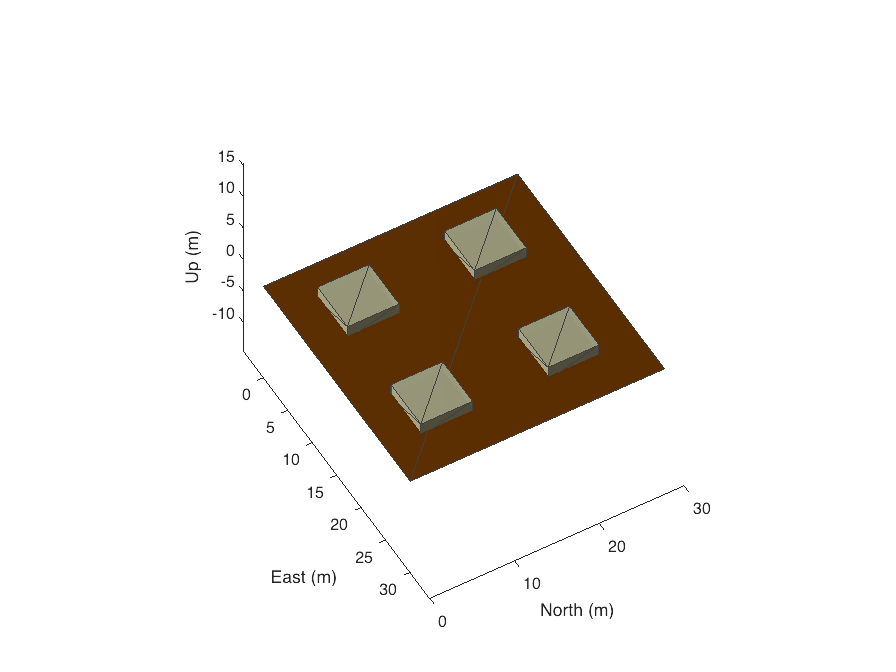

envc = EnvironmentConstants();
[obstacles, scenario, gridSize] = envc.createRobotScenerioEnvironment2();
show3D(scenario);
lightangle(-45,30);
view(60,50);

## Load the agent and create the simulink things

contents = load("experiments_comparison_points/experiment_2_points.mat", "points");
importantCoordinates = contents.points;

## Creating the variables for statistics

numTrials = 100;

numFailures = zeros(numTrials,3);
runTimes = zeros(numTrials,1);
numDeadlocks = zeros(numTrials,1);
numCollisions = zeros(numTrials,1);

distancesTravelled = zeros(numTrials,2);
safetyScores = zeros(numTrials,2);
smoothnessScores = zeros(numTrials,2);

## Create the tasks

rng(0) 
for trial=1:numTrials
    %step 1
    rng(trial)
    selected_indices = randperm(length(importantCoordinates),6);
    locations = importantCoordinates(selected_indices,:);
    %format the input string

    stringInput = embedJSON([locations(1,:); locations(4,:)],[locations(2,:); locations(5,:)], [locations(3,:); locations(6,:)],[locations(1,:); locations(4,:)], [1; 2]);
    tic
    taskControlAgent = TaskControlAgent(gridSize, obstacles);
    reservedRoutes = taskControlAgent.executeControl(stringInput, taskControlAgent.DECENTRALISED);
    toc

    taskControlAgent.tasks.startCoordinates

    runTimes(trial) = toc;

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% ANALYSE THE ROUTES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    [maxElements, longestIdx] = max(cellfun(@numel, reservedRoutes));
    numRows = maxElements/2;
    [minElements, shortestIdx] = min(cellfun(@numel, reservedRoutes));
    
    waypoints = {};
    for rIndex=1:length(reservedRoutes)
        thisRoute = reservedRoutes{rIndex};
        currentLength = size(thisRoute,1);
        if currentLength < numRows
            %if the current route is shorter than the longest one then repeat
            %the end to the right length
            temp = zeros(numRows-currentLength,2);
            temp = temp+thisRoute(end,:);
            reservedRoutes{rIndex} = [thisRoute; temp];
        end
        %adjust the coordinates correctly
        temp = zeros(length(reservedRoutes{rIndex}), 2);
        for rIndex2=1:numRows
            currentCoords = reservedRoutes{rIndex}(rIndex2,:);
            temp(rIndex2,:) = [currentCoords(1)-0.5, currentCoords(2)-0.5]; 
        end
        waypoints{rIndex} = temp;
    end
    route1 = waypoints{1};
    route2 = waypoints{2};
    
    %Calculate the Distance Travelled
    travelDistance1 = distanceTravelled(route1);
    travelDistance2 = distanceTravelled(route2);

    %Calculate the Number of Collisions
    totalLength = size(reservedRoutes{longestIdx},1);
    collisions = 0;
    for lIndex=1:totalLength 
        amr1loc = route1(lIndex,:);
        amr2loc = route2(lIndex,:);
    
        locations = [amr1loc; amr2loc];
        collisions = collisions + checkCollisions(locations);
    end

    %Calculate the Number of Deadlocks
    routes = {route1, route2};
    deadlocks = checkDeadlocks(route1, route2);
    
    
    disp("check")
    numFailures(trial, :)
    deadlocks
    collisions
    disp("__________")

    failures = [0 0 0];
    numFailures(trial,:) = failures;
    numDeadlocks(trial) = deadlocks;
    numCollisions(trial) = collisions;
    
    distancesTravelled(trial,:) = [travelDistance1 travelDistance2];
    smoothnessScores(trial,:) = calculateSmoothnessScores({route1, route2});
    safetyScores(trial,:) = calculateSafetyScores({route1, route2});

    %if collisions > 0 || deadlocks > 0 
    %    [obstacles, scenario, gridSize] = envc.createRobotScenerioEnvironment1();
    %    travelDistances = simulateExperiment(waypoints, tasks, robots, scenario);
    %end
end

Elapsed time is 3.162666 seconds.


ans =     29     5


ans =     23     1


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.662356 seconds.


ans =      1    16


ans =      8    17


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.870744 seconds.


ans =     28     2


ans =      1    16


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.510118 seconds.


ans =     11    30


ans =     29     5


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.472108 seconds.


ans =     29     5


ans =     23     1


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.270844 seconds.


ans =     17    15


ans =     15    25


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.159351 seconds.


ans =     17    15


ans =     11    30


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.783673 seconds.


ans =     17    15


ans =     28     2


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.425544 seconds.


ans =      1    16


ans =      8    17


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.716370 seconds.


ans =     29     5


ans =      9    19


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.742077 seconds.


ans =      9    19


ans =      5     4


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.163198 seconds.


ans =      1    28


ans =     17    15


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.886461 seconds.


ans =     11    30


ans =      5     4


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.674350 seconds.


ans =      5     4


ans =     17    15


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.821822 seconds.


ans =     11    30


ans =     29    26


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.787527 seconds.


ans =      8    17


ans =     17    15


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.439024 seconds.


ans =     17    15


ans =      9    19


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.325273 seconds.


ans = 1×2
     1    28


ans = 1×2
     9    19


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.306570 seconds.


ans = 1×2
     8    17


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.555794 seconds.


ans = 1×2
     9    19


ans = 1×2
     5     4


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.794792 seconds.


ans = 1×2
     8    17


ans = 1×2
     9    19


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.999642 seconds.


ans = 1×2
    28     2


ans = 1×2
     9    19


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.314275 seconds.


ans = 1×2
    29    26


ans = 1×2
     9    19


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.700795 seconds.


ans = 1×2
    15    25


ans = 1×2
     5     4


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.098807 seconds.


ans = 1×2
    23     1


ans = 1×2
     1    16


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.765303 seconds.


ans = 1×2
    17    15


ans = 1×2
     1    16


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.181779 seconds.


ans = 1×2
    29     5


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.023846 seconds.


ans = 1×2
    29    26


ans = 1×2
    15    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.605684 seconds.


ans = 1×2
     9    19


ans = 1×2
    15    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.722462 seconds.


ans = 1×2
    17    15


ans = 1×2
     1    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.523949 seconds.


ans = 1×2
    29     5


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.169300 seconds.


ans = 1×2
    29     5


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.552136 seconds.


ans = 1×2
     8    17


ans = 1×2
     1    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.182472 seconds.


ans = 1×2
     9    19


ans = 1×2
    28     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.179306 seconds.


ans = 1×2
     1    16


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.367867 seconds.


ans = 1×2
    23     1


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.189359 seconds.


ans = 1×2
     9    19


ans = 1×2
     1    16


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.775748 seconds.


ans = 1×2
    17    15


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.976526 seconds.


ans = 1×2
    17    15


ans = 1×2
     5     4


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.640245 seconds.


ans = 1×2
     8    17


ans = 1×2
    29     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.178415 seconds.


ans = 1×2
    15    25


ans = 1×2
     9    19


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.575541 seconds.


ans = 1×2
    29     5


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.166187 seconds.


ans = 1×2
     8    17


ans = 1×2
    23     1


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.171665 seconds.


ans = 1×2
     1    16


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.602966 seconds.


ans = 1×2
     1    16


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.480078 seconds.


ans = 1×2
    29    26


ans = 1×2
     9    19


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.298540 seconds.


ans = 1×2
     5     4


ans = 1×2
    17    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.385173 seconds.


ans = 1×2
     5     4


ans = 1×2
    17    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.194882 seconds.


ans = 1×2
     1    16


ans = 1×2
     5     4


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.290725 seconds.


ans = 1×2
    23     1


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.337203 seconds.


ans = 1×2
    23     1


ans = 1×2
    29     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.003828 seconds.


ans = 1×2
     9    19


ans = 1×2
    11    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.059095 seconds.


ans = 1×2
    15    25


ans = 1×2
    23     1


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.352312 seconds.


ans = 1×2
     1    28


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.659413 seconds.


ans = 1×2
     8    17


ans = 1×2
     5     4


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.996723 seconds.


ans = 1×2
    15    25


ans = 1×2
    17    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.181747 seconds.


ans = 1×2
    29     5


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.352395 seconds.


ans = 1×2
    29    26


ans = 1×2
     5     4


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.910683 seconds.


ans = 1×2
    29     5


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.113743 seconds.


ans = 1×2
    29     5


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.571712 seconds.


ans = 1×2
    15    25


ans = 1×2
    28     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.944454 seconds.


ans = 1×2
     8    17


ans = 1×2
    23     1


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.225570 seconds.


ans = 1×2
    17    15


ans = 1×2
    29     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.704262 seconds.


ans = 1×2
    17    15


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.334624 seconds.


ans = 1×2
    17    15


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.221341 seconds.


ans = 1×2
     1    28


ans = 1×2
    23     1


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.560751 seconds.


ans = 1×2
     9    19


ans = 1×2
    29     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.977556 seconds.


ans = 1×2
     8    17


ans = 1×2
    11    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.455365 seconds.


ans = 1×2
     1    28


ans = 1×2
    15    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.399521 seconds.


ans = 1×2
    15    25


ans = 1×2
    29     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.569423 seconds.


ans = 1×2
    15    25


ans = 1×2
    11    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.310889 seconds.


ans = 1×2
    29     5


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.679062 seconds.


ans = 1×2
    23     1


ans = 1×2
    29     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.187285 seconds.


ans = 1×2
     8    17


ans = 1×2
    29     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.677389 seconds.


ans = 1×2
     1    16


ans = 1×2
    15    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.817625 seconds.


ans = 1×2
     8    17


ans = 1×2
     1    16


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.032969 seconds.


ans = 1×2
    29     5


ans = 1×2
    15    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.288157 seconds.


ans = 1×2
    17    15


ans = 1×2
    29     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.488553 seconds.


ans = 1×2
     5     4


ans = 1×2
    11    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.734430 seconds.


ans = 1×2
    17    15


ans = 1×2
     1    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.217350 seconds.


ans = 1×2
     9    19


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.137609 seconds.


ans = 1×2
    28     2


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.887988 seconds.


ans = 1×2
    17    15


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.779253 seconds.


ans = 1×2
    23     1


ans = 1×2
    17    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.423748 seconds.


ans = 1×2
    11    30


ans = 1×2
    29     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.022545 seconds.


ans = 1×2
    29    26


ans = 1×2
     1    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.166065 seconds.


ans = 1×2
     1    28


ans = 1×2
     1    16


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.241260 seconds.


ans = 1×2
    29     5


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.129233 seconds.


ans = 1×2
     9    19


ans = 1×2
     1    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.837019 seconds.


ans = 1×2
    29    26


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.509828 seconds.


ans = 1×2
     8    17


ans = 1×2
    28     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.153619 seconds.


ans = 1×2
    29    26


ans = 1×2
    17    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.480926 seconds.


ans = 1×2
     9    19


ans = 1×2
     5     4


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.313211 seconds.


ans = 1×2
    11    30


ans = 1×2
     1    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.343644 seconds.


ans = 1×2
    17    15


ans = 1×2
     5     4


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.017298 seconds.


ans = 1×2
     5     4


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.031456 seconds.


ans = 1×2
    11    30


ans = 1×2
    28     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.956566 seconds.


ans = 1×2
    29    26


ans = 1×2
     9    19


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.869817 seconds.


ans = 1×2
     1    16


ans = 1×2
    11    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.427676 seconds.


ans = 1×2
    11    30


ans = 1×2
     1    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________



%Run Times
runTimes

runTimes = 100×1
    3.2246
    3.6890
    3.8965
    3.5331
    3.5855
    3.2893
    2.1916
    2.7938
    3.4622
    3.7559


numFailures

numFailures = 100×3
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


numDeadlocks

numDeadlocks = 100×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


numCollisions

numCollisions = 100×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


distancesTravelled

distancesTravelled = 100×2
    50    98
    86    86
    72    98
    72    80
    80    98
    72    78
    64    46
    56    92
   104    66
   104    54


smoothnessScores

smoothnessScores = 100×2
    4.7124   12.5664
   10.9956   14.1372
   10.9956    6.2832
   12.5664   14.1372
   14.1372   12.5664
   12.5664   10.9956
    9.4248    7.8540
    9.4248    6.2832
    6.2832   15.7080
   12.5664   12.5664


safetyScores

safetyScores = 100×2
     0     0
     7     7
     0     0
     8     8
    15    15
     3     3
     0     0
    12    12
     1     1
     0     0


save('experiments_comparison_results/experiment_2_new_decentralised_ga.mat','runTimes','numFailures','numDeadlocks','numCollisions','distancesTravelled','smoothnessScores','safetyScores');